# Main con un robot e 3 ostacoli

Initial configuration space (goal, obstacles, robot)

clear; close all;
grid = Grid(2,0,10);
G = [5,10]; grid.setGoal([5,10]);

Obstacles and robot initial configuration

grid.addObstacle(Obstacle(5,5,[0;0]));
% grid.addObstacle(Obstacle(10,6,[0;1]));
% grid.addObstacle(Obstacle(2,10,[0.5;-0.5]));
n = length(grid.obstacles);
r = Robot(5,1);

Modules

sense = Sense(r,grid);
plan = Plan(r,grid);
act = Act(r,grid);

SENSE

e = norm([r.xc,r.yc]-G); tsim = 0; tspan = 0.1;
while(e > 0.1 && tsim < 15)
    rx = r.xc; ry = r.yc; rtheta = r.theta;
    dObstacle = sense.scan();

PLAN

    plan = plan.decide(dObstacle);

ACT

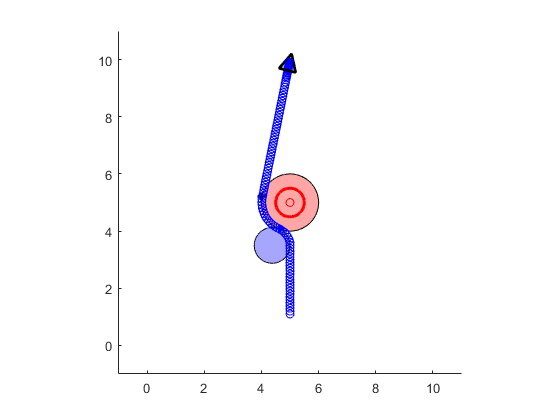

    act.move(plan.gradX,plan.gradY,tspan);

    for k = 1:n
        grid.obstacles(k).move(tspan);
    end
    e = norm([rx,ry]-G);
    if e <= 1 && e >= 0.8
        agradX = G(1)-grid.X; agradY = G(2)-grid.Y;
        plan = plan.setGrad(agradX,agradY);
    end

plan =   Plan with properties:

    agradX: [1001×1001 double]
    agradY: [1001×1001 double]
     gradX: [1001×1001 double]
     gradY: [1001×1001 double]
    gradXO: [1001×1001 double]
    gradYO: [1001×1001 double]
        P1: [4.6154 4.0769]
        P2: [4.0202 5.2000]
    solxp2: [2×1 sym]
    solyp2: [2×1 sym]
     robot: [1×1 Robot]
      grid: [1×1 Grid]
     state: attractive


plan =   Plan with properties:

    agradX: [1001×1001 double]
    agradY: [1001×1001 double]
     gradX: [1001×1001 double]
     gradY: [1001×1001 double]
    gradXO: [1001×1001 double]
    gradYO: [1001×1001 double]
        P1: [4.6154 4.0769]
        P2: [4.0202 5.2000]
    solxp2: [2×1 sym]
    solyp2: [2×1 sym]
     robot: [1×1 Robot]
      grid: [1×1 Grid]
     state: attractive


    tsim = tsim + tspan; pause(0);
end